%  Set up directories
% Folder where images are stored
%     im_dir= 'D:\Emi\Saleem lab project\Animal 11\Immuno\Tiff\Slide 4 immuno\subtact_debris';
    im_dir='C:\Users\m.morimoto\OneDrive - University College London\Code\subtractDebris';

% Filenames
    filename_red=['red' '.tif'];
    filename_farred=['farred' '.tif'];
    
% Output filenames
    output_filename_red='red_edit.tif';
    output_filename_farred='farred_edit.tif';


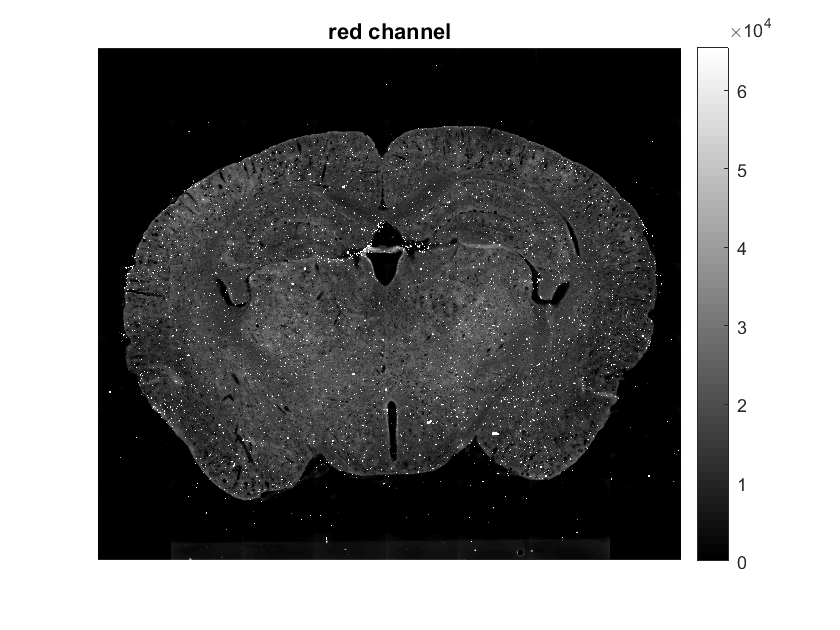


% Load red channel image
    InfoImage.red=imfinfo([im_dir filesep filename_red]);
    im_red=zeros(InfoImage.red.Height,InfoImage.red.Width,length(InfoImage.red),'double');

    TifLink = Tiff([im_dir filesep filename_red], 'r');
    for i=1:length(InfoImage.red)
       TifLink.setDirectory(i);
       im_red(:,:,i)=TifLink.read();
    end
    TifLink.close();

    figure(98);
    imagesc(im_red)
    colormap gray; 
    colorbar
    axis off; axis equal
    title('red channel')

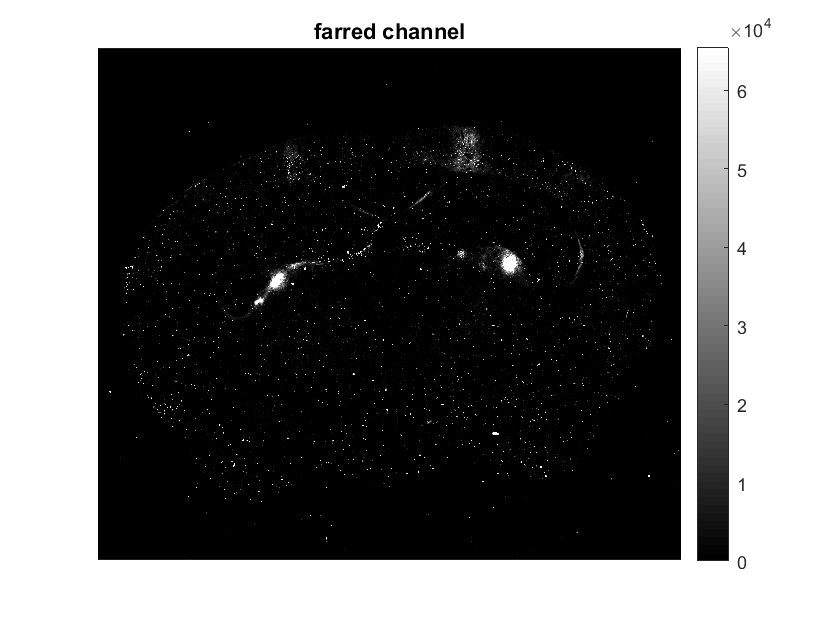

    
% Load far red channel image
    InfoImage.farred=imfinfo([im_dir filesep filename_farred]);
    im_farred=zeros(InfoImage.farred.Height,InfoImage.farred.Width,length(InfoImage.farred),'double');

    TifLink = Tiff([im_dir filesep filename_farred], 'r');
    for i=1:length(InfoImage.farred)
       TifLink.setDirectory(i);
       im_farred(:,:,i)=TifLink.read();
    end
    TifLink.close();

    figure(99);
    imagesc(im_farred)
    colormap gray; 
    colorbar
    axis off; axis equal
    title('farred channel')

    
% binary mask 1
thresh1=max(max(im_red))*0.8;
mask1=double(im_red>thresh1);% convert logical to double
% binary mask 2
thresh2=max(max(im_farred))*0.8;
mask2=double(im_farred>thresh2);
% generate common mask
mask=mask1.*mask2;
% dilate debris 1 pixel
se = strel('square',7);
mask_dil = imdilate(mask,se);

figure;
imshowpair(mask, mask_dil)

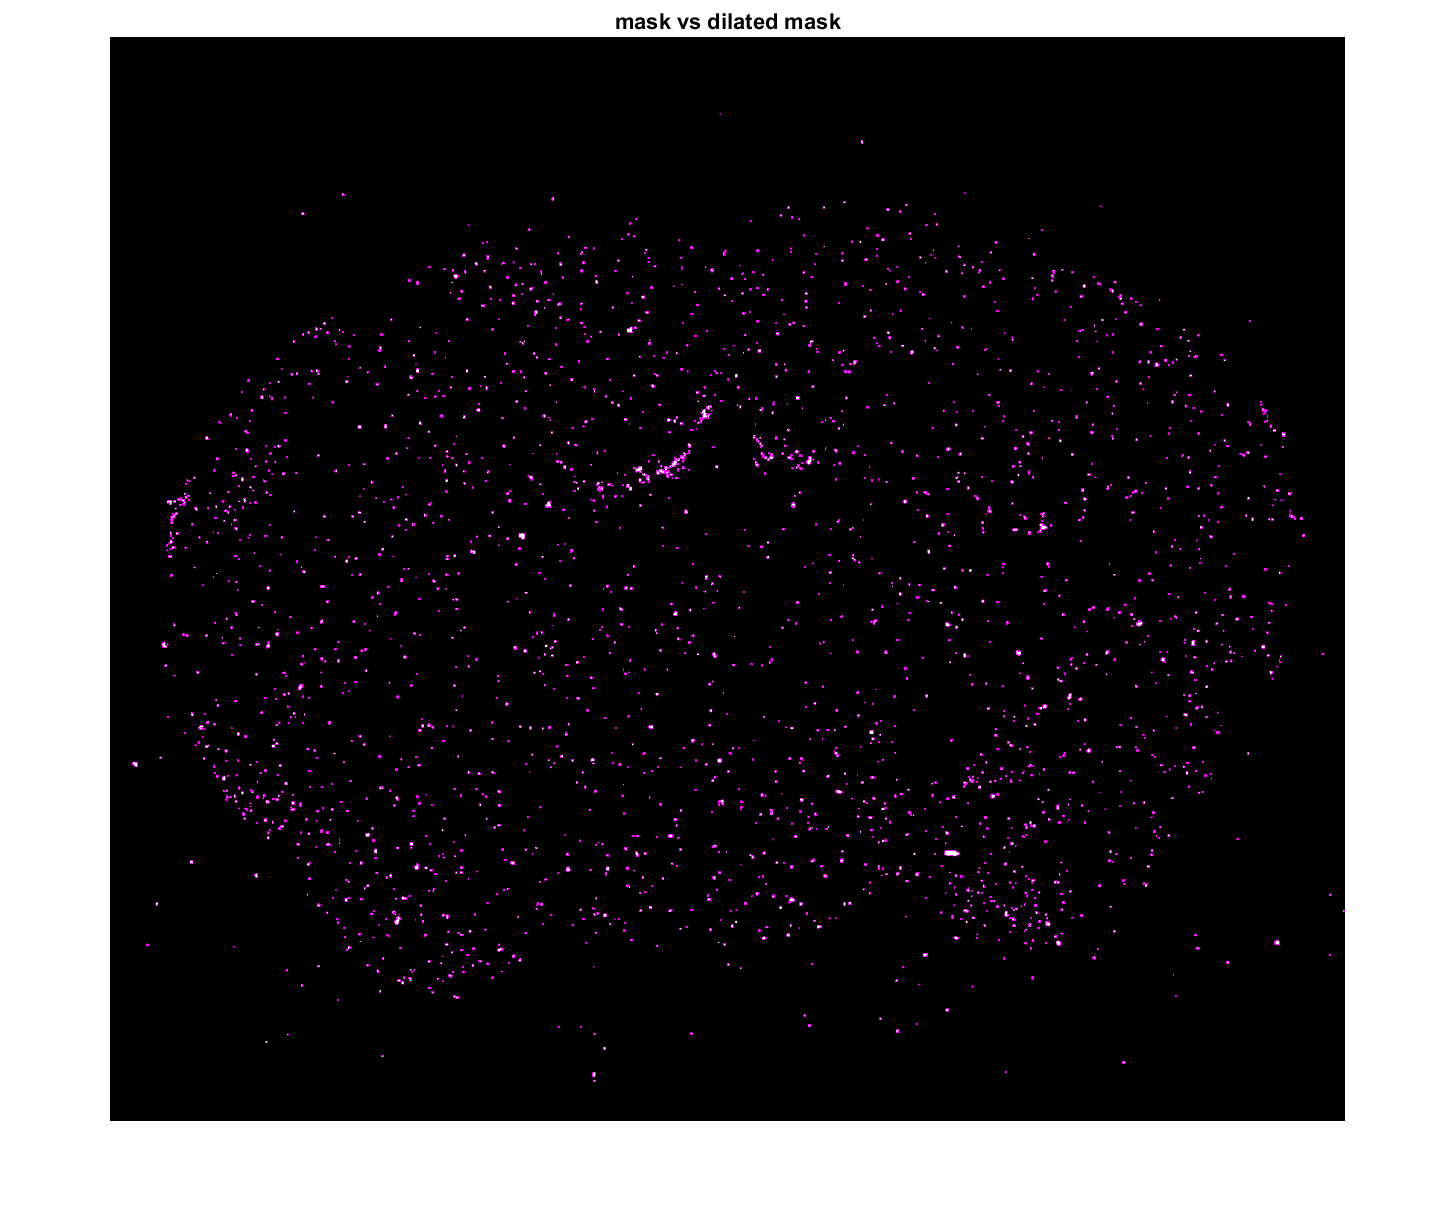

axis off; axis equal
title('mask vs dilated mask')

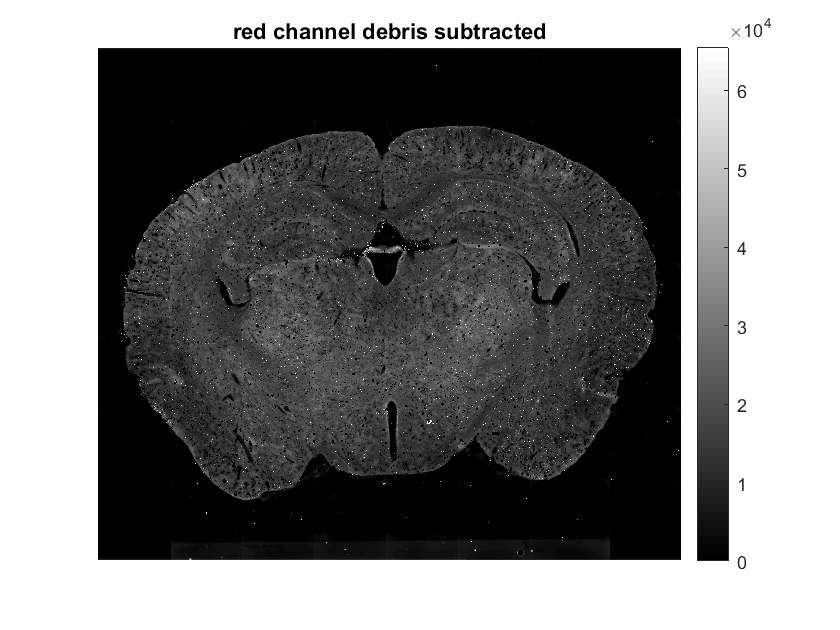


% invert mask
inv_mask=abs(mask_dil-1);
% apply mask to both channels
im_red_new=im_red.*inv_mask;
im_farred_new=im_farred.*inv_mask;

figure;
imagesc(im_red_new)
colormap gray; 
colorbar
axis off; axis equal
title('red channel debris subtracted')

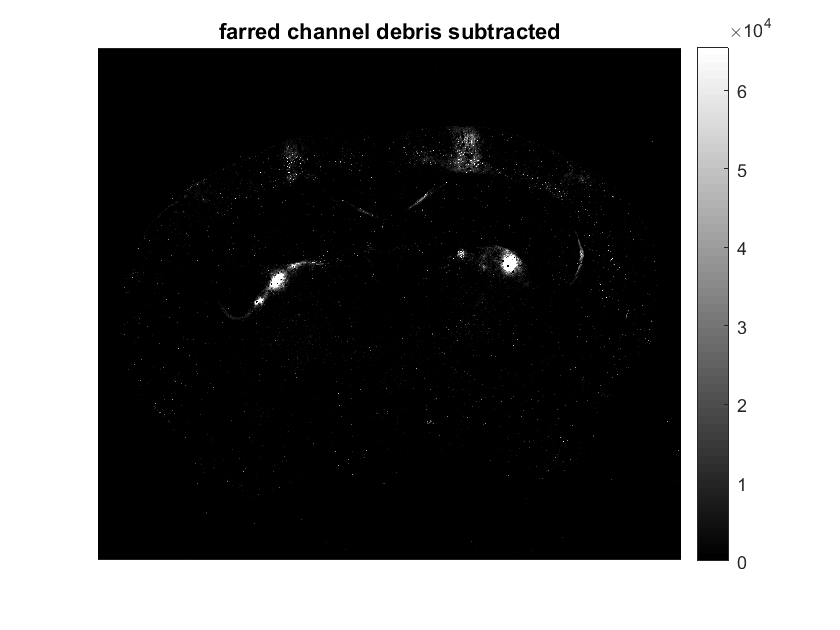


figure;
imagesc(im_farred_new)
colormap gray; 
colorbar
axis off; axis equal
title('farred channel debris subtracted')


im_red_new_8bit =im_red_new/65280*255;
im_red_new_16bit =uint16(im_red_new);

imwrite(im_red_new,[im_dir filesep output_filename_red],'ColorSpace','cielab')
imwrite(im_red_new_8bit,[im_dir filesep output_filename_red])
imwrite(im_red_new_16bit,[im_dir filesep output_filename_red])





